# Lattice Modulation, Scan lattice depth

## Set atom and magnetic field

% atom
atom = Alkali("Lithium7");

% B field
bList = num2cell(1.2317e-2);
niB = 543.6e-4; %non-interacting feshbach field
bField = cellfun(@(x) MagneticField(...
    bias = [0;0;niB],...
    gradient = [0,0,0;0,0,0;0,x,0]),bList,'UniformOutput',false);

## Set benchmark simulation

nRun = 96;
% set laser
laser0 = GaussianBeam( ...
    wavelength = 1064e-9,...
    direction = [0;1;0],...
    polarization = [0;0;1],...
    power = 0.6, ...
    waist = 110e-6 ...
    );
laser = cell(1,nRun);

% set optical lattice
depthList = linspace(8.8458 - 0.5,8.8458 + 0.5,nRun);
for ii = 1:nRun
    ol = OpticalLattice(atom,laser0);
    ol.DepthSpec = depthList(ii) * ol.RecoilEnergy;
    ol.updateIntensity;
    laser{ii} = GaussianBeam( ...
    wavelength = 1064e-9,...
    direction = [0;1;0],...
    polarization = [0;0;1],...
    power = ol.Laser.Power, ...
    waist = 110e-6 ...
    );
end

% set modulation
nMod = 1;
modFreq = linspace(89,89,nMod) * 1e3;
modu = cell(1,nMod);
for ii = 1:nMod
    modu{ii} = [
        Modulation(...
        depth = 0.035, ...
        duration = 15e-3, ...
        frequency = 143.2231e3, ...
        timing = 0)
        ];
end

% set spacegrid
sRange = 1000e-06;
sStep = 1e-8;
nStep = getNSpaceStep(sRange,sStep);
x = linspace(-sRange/2,sRange/2,nStep);
x = x.';

% set initial condition
ic = InitialCondition("SeSim1D");
ic = repmat(ic,1,nRun);
sigma = 50e-6;
kL = ol.Laser.AngularWavenumber;
qmin = - kL;
qmax =  kL;
qList = linspace(qmin,qmax,5000);
qList = qList(1:end-1);
[~,qIdx] = min(abs(qList - 0.7*kL));

for ii = 1:nRun
    ol = OpticalLattice(atom,laser{ii});
    ol.computeBand1D(qList,1);
    ck = ol.FourierComponentList;
    vn = ck(:,2,qIdx).';
    vn = repmat(vn,numel(x),1);
    nmax = max(2 * 2+49,303);
    k = (1-nmax:2:nmax-1) * kL;
    k = repmat(k,numel(x),1);
    temp = vn.* exp(1i*(k+qList(qIdx)).* x);
    phi = sum(temp,2);
    psi = exp(-(x).^2 / 4 / sigma^2) .* phi;
    ic(ii).WaveFunction = psi;
end

% set simulation
se = LatticeSeSim1D("Test", ...
    laser = laser,...
    magneticField = bField,...
    latticeModulation = modu,...
    timeStep=1e-7,...
    totalTime=3.33e-3,...
    spaceRange = sRange,...
    spaceStep = sStep,...
    initialCondition = ic);

Constructing the object.
Setting up folders.
Creating a database entry.
Updating the object file.



% start
se.start

Updating the object file.
Python Error: ValueError: There is no data available on HFS structure of 2 P 3/2 state
> In parallel.internal.pool.optionallyDeserialize (line 7)
In parallel.internal.parfor.cppRemoteParallel

## Plot

% plot benchmark
trialNumber = 17;
obj = loadTrial(createReader("simulation"),"lattice_schrodinger_equation_simulation_1d",trialNumber);
% obj.SimRun(1).showSpaceTime
nRun = numel(obj.SimRun);
freqList = zeros(1,nRun);
ampList = zeros(1,nRun);
for ii = 1:nRun
    rawData = obj.SimRun(ii).showPeak;
    fitData = SineFit1D(rawData);
    fitData.do;
    freqList(ii) = fitData.Coefficient(2);
    ampList(ii) = fitData.Coefficient(1);
end

## Analysis: animation

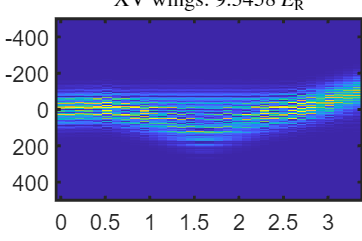

trialNumber = 17;
filename = "AI20240528.gif";
startDelay=.5;
midDelay=.1;
endDelay=.5;
obj = loadTrial(createReader("simulation"),"lattice_schrodinger_equation_simulation_1d",trialNumber);
nSpace = obj.SimRun(1).NSpaceStep;
nRun = numel(obj.SimRun);
psiList = zeros(nRun,nSpace);
psi1 = obj.SimRun(1).readRun("WaveFunction");
psi1 = psi1(1,:);
n1 = abs(psi1).^2;
nLim = max(n1);
for ii = 1:nRun
    psiList(ii,:) = obj.SimRun(ii).readRun("FinalWaveFunction");
    obj.SimRun(ii).showSpaceTime;
    fig = gcf;
    imgAxes = gca;
    imgAxes.CLim = [0,nLim];

    % Update title
    imgAxes.Title.String = "XV wings: $" + num2str(depthList(ii)) + "~E_{\mathrm{R}}$";
    imgAxes.Title.Interpreter = "latex";
    render

    % Save as gif
    frame = getframe(fig);
    im = frame2im(frame);
    [A,map] = rgb2ind(im,256);
    if ii == 1
        imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',startDelay);
    else
        if ii==nRun
            imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',endDelay);
        else
            imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',midDelay);
        end
    end
end

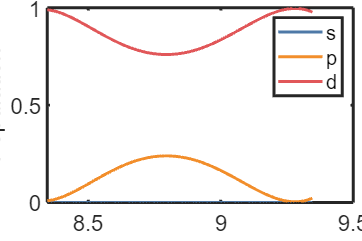

x = obj.SimRun(1).SpaceList;
bandPop = ol.computeBandPopulation1D(psiList,int32(2),x);
% bListGauss = cell2mat(bList) * 1e2;
figure
plot(depthList,bandPop)
xlabel("Lattice Depth [Er]")
ylabel("Population")
legend("s","p","d")
render
saveas(gcf,"AI20240531","png")